# System 1

clc; clear;
% Symbolic Variables:
syms t alpha(t) beta(t) gamma(t)
syms D_1 D_2 L_1 L_2
syms m_1 m_2
syms I_1x I_1y I_1z I_2x I_2y I_2z

I_1_G1_1 = diag([I_1x, I_1y, I_1z]);
I_2_G2_2 = diag([I_2x, I_2y, I_2z]);



## 1) Setup Frames

% Positive rotation around y axis.
R0b = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 0];
Rb0 = R0b';

% Negative rotation around y axis.
Rba = [cos(beta) 0 -sin(beta); 0 1 0; sin(beta) 0 cos(beta)];
Rab = Rba.';

% Negative rotation around z axis.
Rae = [1 0 0; 0 cos(gamma) sin(gamma); 0 -sin(gamma) cos(gamma)];
Rea = Rae.';

## 2) Angular Velocities

wb_b = [0; 0; diff(alpha)];

wab_a = [0; -diff(beta); 0];
wa_a = wab_a + Rab*wb_b;

web_e = [-diff(gamma); 0; 0];
we_e = web_e + Rea*wab_a + Rea*Rab*wb_b;

## 3) Position Vectors

## 4) Velocity and Acceleration Vectors

syms alpha_dot(t) beta_dot(t) alpha_ddot beta_ddot % not functions of time, for later



## 5) Angular Momentum

## 6) FBDs

Link 1

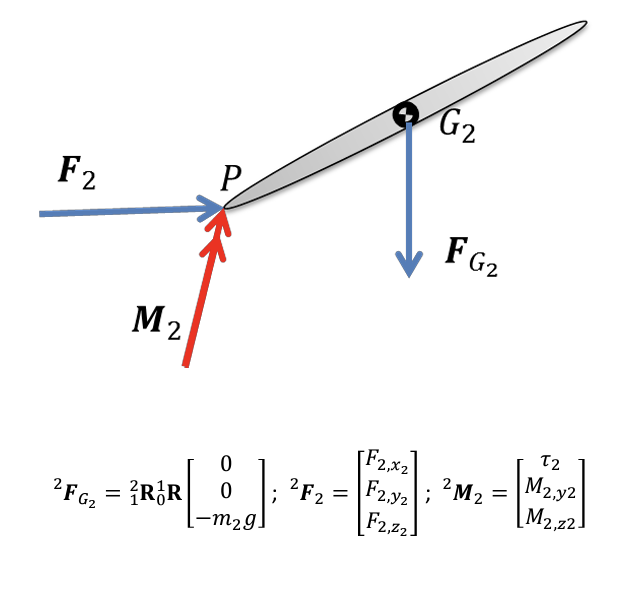

syms F2x F2y F2z tau_2 M2y M2z g


Link 2

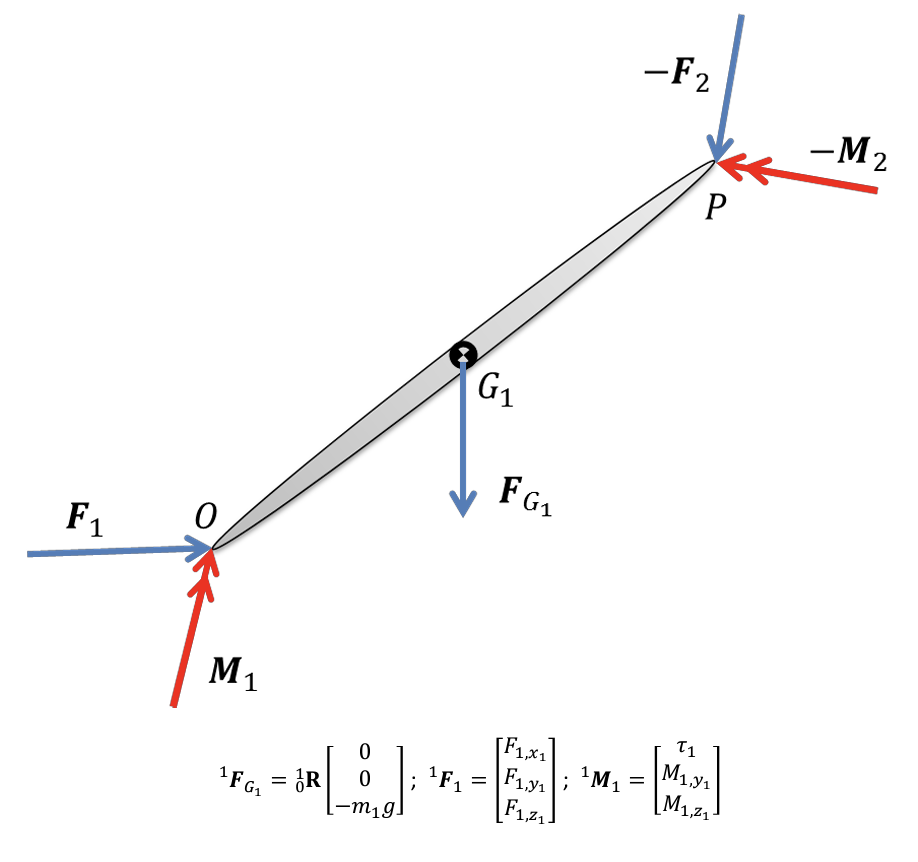

syms F1x F1y F1z tau_1 M1y M1z



## Isolating Equations